% AUTOMATIC COIN COUNTER USING IMAGE PROCESSING
% Author: Chickenwing
% Description: Detects and counts coins in an image using image processing.

clc;
clear;
close all;

## 1. Image Accquisition

Read the input image

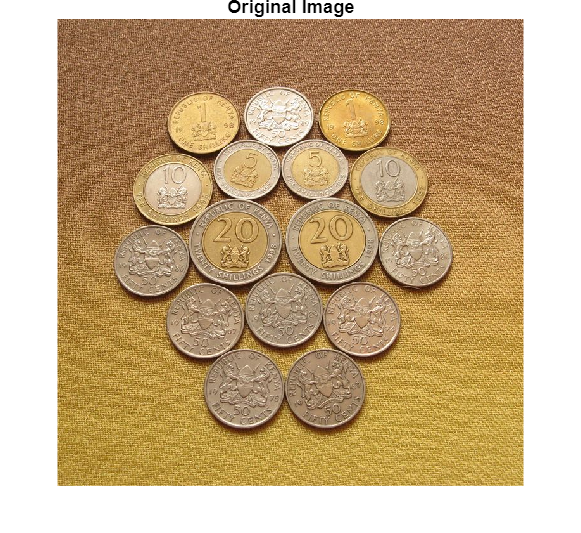

img = imread('numerous coins.jfif'); % <-- Replace with your image filename

figure;
imshow(img);
title('Original Image');

## 2. Image processing

Convert to grayscale

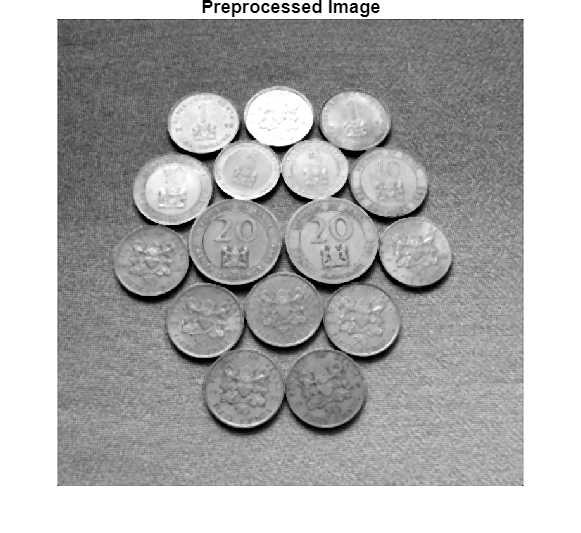

if size(img,3) == 3
    graying = rgb2gray(img);
else
    graying = img;
end

% Apply median filtering to reduce noise
filteredimg = medfilt2(graying, [5 5]);

%Enhance contrast
enhancedimg = imadjust(filteredimg);

figure;
imshow(enhancedimg);
title('Preprocessed Image');

## 3. Image segmentation

Convert to binary image using Otsu's thresholding

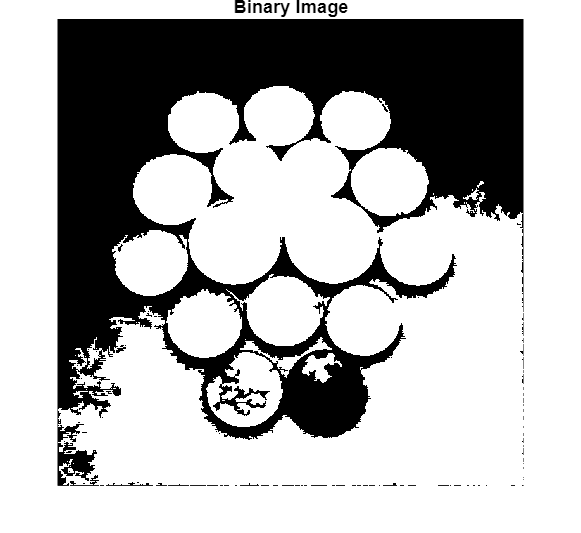

bw = imbinarize(enhancedimg);

% Invert image if needed(coins should be white)
if mean(bw(:))<0.5
    bw = ~bw;
end

% Remove small objects (noise)
bw = bwareaopen(bw, 500);

% Fill holes inside coins
bw = imfill(bw, 'holes');

figure;
imshow(bw);
title('Binary Image');

## 4. Coin Detection

Use imfindcircles for circle detection

[centers, radii, metric] = imfindcircles(bw, [20 100], 'Sensitivity',0.92);

% If imfindcirles fails, use regionprops as fallback
if isempty(centers)
    disp('imfindcircles did not find coins. Using regionprops...');
    labeled = bwlabel(bw);
    stats = regioprops(labeled, 'Centroid', 'EquivDiameter');
    centers = cat(1, stats.Cebtroid);
    radii = cat(1, stats.EquivDiameter)/2;
end

## 5. feature Extraction and Counting

numCoins = length(radii);


## 6. Output Results

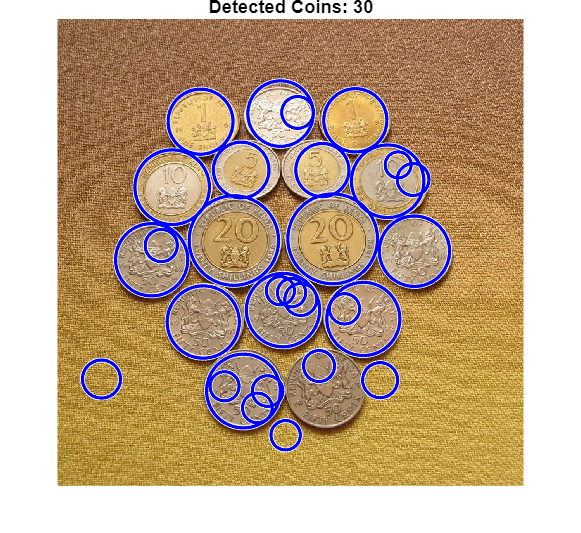

% Show detected coins on the image
figure;
imshow(img);
viscircles(centers, radii,'EdgeColor','b');
title(['Detected Coins: ', num2str(numCoins)]);


fprintf('Total number of coins detected: %d\n', numCoins);

Total number of coins detected: 30



% Optional: Show radii for each coin
for i = 1:numCoins
    fprintf('Coin %d: center=(%.1f, %.1f), radius=%.1f px\n', i, centers(i,1), centers(i,2), radii(i));
end

Coin 1: center=(483.5, 473.3), radius=57.7 px
Coin 2: center=(356.6, 459.3), radius=57.8 px
Coin 3: center=(226.4, 162.3), radius=51.3 px
Coin 4: center=(149.3, 380.0), radius=57.0 px
Coin 5: center=(230.7, 478.1), radius=57.0 px
Coin 6: center=(181.6, 265.6), radius=58.8 px
Coin 7: center=(564.3, 366.5), radius=55.5 px
Coin 8: center=(352.8, 149.6), radius=51.6 px
Coin 9: center=(435.1, 347.1), radius=70.8 px
Coin 10: center=(294.2, 586.9), radius=58.1 px
Coin 11: center=(521.9, 256.2), radius=57.2 px
Coin 12: center=(470.9, 160.2), radius=49.8 px
Coin 13: center=(290.6, 238.5), radius=43.9 px
Coin 14: center=(279.1, 349.7), radius=70.6 px
Coin 15: center=(418.8, 238.6), radius=41.9 px
Coin 16: center=(316.1, 613.5), radius=23.4 px
Coin 17: center=(379.8, 147.7), radius=25.1 px
Coin 18: center=(562.1, 253.5), radius=25.1 px
Coin 19: center=(453.9, 457.4), radius=23.9 px
Coin 20: center=(264.3, 579.4), radius=22.9 px
Coin 21: center=(352.5, 428.8), radius=22.2 px
Coin 22: center=(332.3


% Optional: Estimate value if you classified coins by size


## 7. Save Results (optional)

% imwrite( getframe(gca).cdata, 'coins_detected.jpg');

% End of script